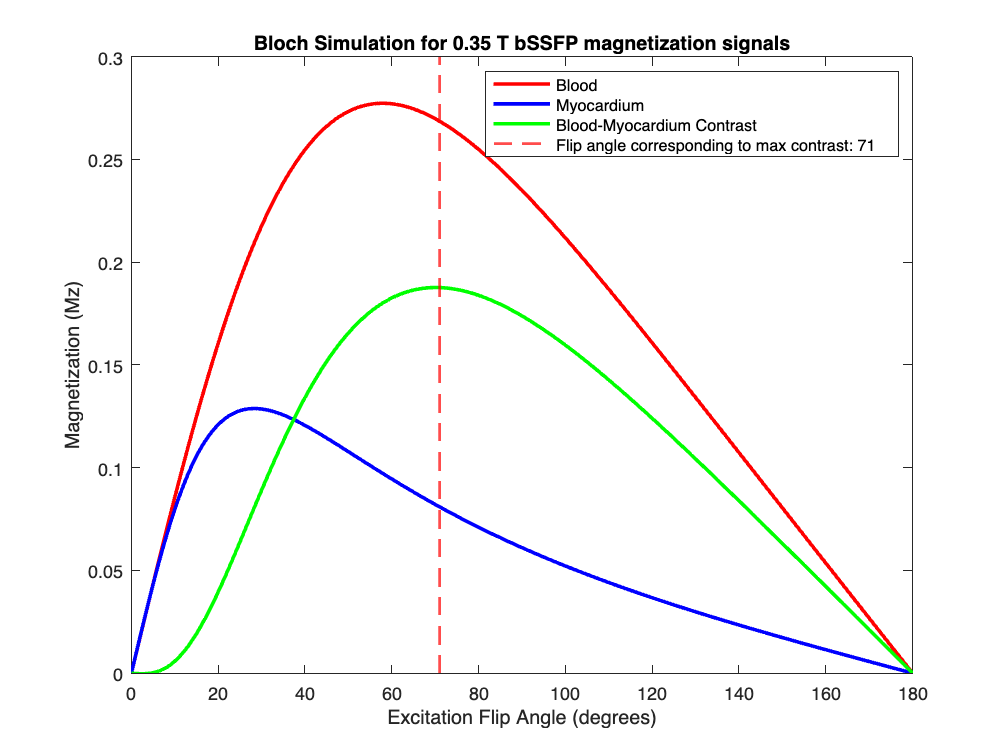

%% Bloch Simulation for CMR Plot

% Constants
T1_blood_0_35T = 1144; % Expected T1 of blood at 0.35 T in ms
T1_myocardium_0_35T = 708; % Expected T1 of myocardium at 0.35 T in ms
T2_blood_0_35T = 350; % T2 of blood at 0.35 T in ms
T2_myocardium_0_35T = 45; % T2 of myocardium at 0.35 T in ms

T1_blood_1_5T = 1613; % Expected T1 of blood at 1.5 T in ms
T1_myocardium_1_5T = 1170; % Expected T1 of myocardium at 1.5 T in ms
T2_blood_1_5T = 300; % T2 of blood at 1.5 T in ms
T2_myocardium_1_5T = 40; % T2 of myocardium at 1.5 T in ms


TR = 4; % Repetition time in ms
TE = 1; % Echo time in ms

alpha = deg2rad(0:180);
% Plot Bloch Simulation for 0.35 T bSSFP magnetization signals
Mxy_blood =   (1-exp(-TR./T1_blood_0_35T)) .* exp(-TE./T2_blood_0_35T) .* sin(alpha) ./ (1-(exp(-TR./T1_blood_0_35T)- exp(-TR./T2_blood_0_35T))*cos(alpha) -   exp(-TR./T1_blood_0_35T).*exp(-TR./T2_blood_0_35T));
Mxy_myocardium =   (1-exp(-TR./T1_myocardium_0_35T)) .* exp(-TE./T2_myocardium_0_35T) .* sin(alpha) ./ (1-(exp(-TR./T1_myocardium_0_35T)- exp(-TR./T2_myocardium_0_35T))*cos(alpha) -   exp(-TR./T1_myocardium_0_35T).*exp(-TR./T2_myocardium_0_35T));
Mxy_Contrast_ = Mxy_blood - Mxy_myocardium;

plot(rad2deg(alpha),Mxy_blood,'r-', 'LineWidth', 2);
hold on;
plot(rad2deg(alpha),Mxy_myocardium,'b-', 'LineWidth', 2);
plot(rad2deg(alpha),Mxy_Contrast_,'g-', 'LineWidth', 2);

xlabel('Excitation Flip Angle (degrees)');
ylabel('Magnetization (Mz)');

[maxValues, maxIndices] = max(Mxy_Contrast_);

xline(maxIndices, '--r', 'LineWidth', 1.5);

legendEntry = ['Flip angle corresponding to max contrast: ', num2str(maxIndices)];
legend('Blood', 'Myocardium', 'Blood-Myocardium Contrast',legendEntry);

title('Bloch Simulation for 0.35 T bSSFP magnetization signals');
hold off;ylim([0, 0.3]);

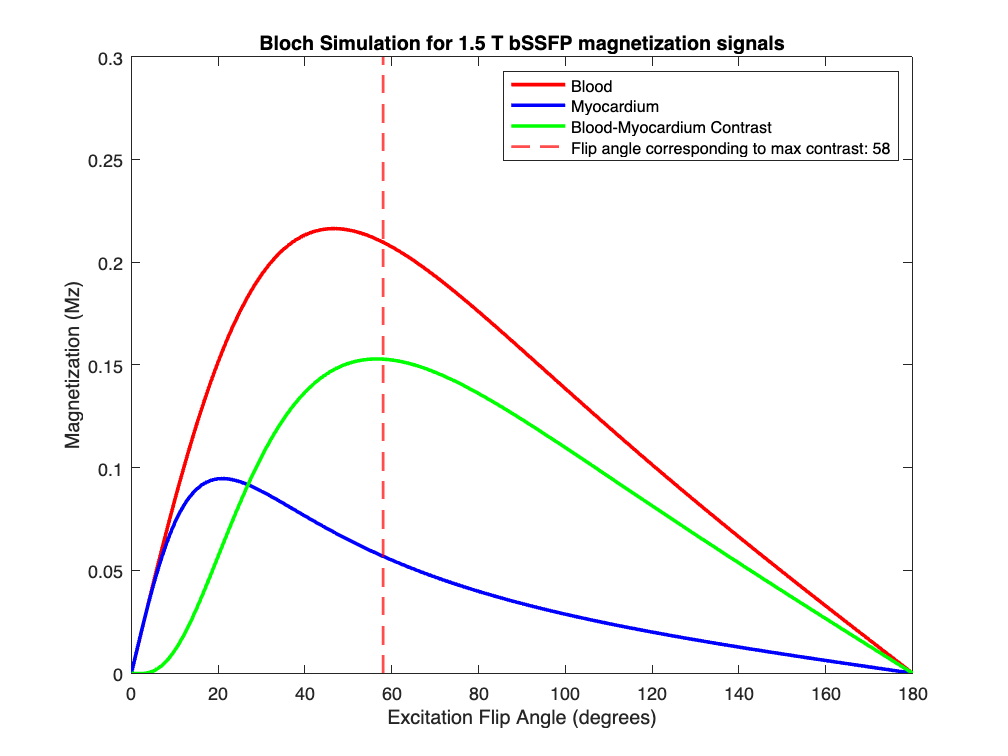

% Plot Bloch Simulation for 1.5 T bSSFP magnetization signals
Mxy_blood_1_5 =   (1-exp(-TR./T1_blood_1_5T)) .* exp(-TE./T2_blood_1_5T) .* sin(alpha) ./ (1-(exp(-TR./T1_blood_1_5T)- exp(-TR./T2_blood_1_5T))*cos(alpha) -   exp(-TR./T1_blood_1_5T).*exp(-TR./T2_blood_1_5T));
Mxy_myocardium_1_5 =   (1-exp(-TR./T1_myocardium_1_5T)) .* exp(-TE./T2_myocardium_1_5T) .* sin(alpha) ./ (1-(exp(-TR./T1_myocardium_1_5T)- exp(-TR./T2_myocardium_1_5T))*cos(alpha) -   exp(-TR./T1_myocardium_1_5T).*exp(-TR./T2_myocardium_1_5T));
Mxy_Contrast_1_5 = Mxy_blood_1_5 - Mxy_myocardium_1_5;

plot(rad2deg(alpha),Mxy_blood_1_5,'r-', 'LineWidth', 2);
hold on;
plot(rad2deg(alpha),Mxy_myocardium_1_5,'b-', 'LineWidth', 2);
plot(rad2deg(alpha),Mxy_Contrast_1_5,'g-', 'LineWidth', 2);

[maxValues, maxIndices] = max(Mxy_Contrast_1_5);

xline(maxIndices, '--r', 'LineWidth', 1.5);

xlabel('Excitation Flip Angle (degrees)');
ylabel('Magnetization (Mz)');
legendEntry = ['Flip angle corresponding to max contrast: ', num2str(maxIndices)];
legend('Blood', 'Myocardium', 'Blood-Myocardium Contrast',legendEntry);
title('Bloch Simulation for 1.5 T bSSFP magnetization signals');
hold off;ylim([0, 0.3]);